# ***Linear Control System***

# ***Matin Mb - 400102114***

# *CHW2*

## *Assignment N.O. 2*

***Section 6 ( *****Frequency Response Analysis using **ss()**, **tf()**, and **zpk() ***): ***

**General Steps:**

- **State-Space to Transfer Function:** Define the state-space system using `ss()` and convert it to transfer function form using `tf()`.

- **Zero-Pole-Gain:** Convert the transfer function to zero-pole-gain form using `zpk()` and interpret the system’s behavior from poles and zeros.

- **Simulink Simulation:** Build a Simulink model with a Sine Wave input, State-Space block, and Scope to visualize the output for a 5 rad/s frequency.

- **Closed-Loop System: **Create a closed-loop system with unity feedback using `feedback()`, compare the step responses of open-loop and closed-loop systems, and analyze the effect of varying feedback gain.

**Initial Code:**

clc; clear; close all;

**Part 1:**

A = [0 1; -2 -3];
B = [0; 1];
C = [1 0];
D = 0;
sys = ss(A, B, C, D);

G = tf(sys)

G =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



**Part 2:**

G_zpk = zpk(G)

G_zpk =
 
       1
  -----------
  (s+2) (s+1)
 
Continuous-time zero/pole/gain model.



- **Poles**: These indicate the system’s natural frequencies and are related to stability. Poles in the left half of the complex plane mean the system is stable.

- **Zeros**: These affect the frequency response, impacting specific frequencies that the system can attenuate or amplify.

**Part 3: (SIMULINK)**

First We designed the model as below:

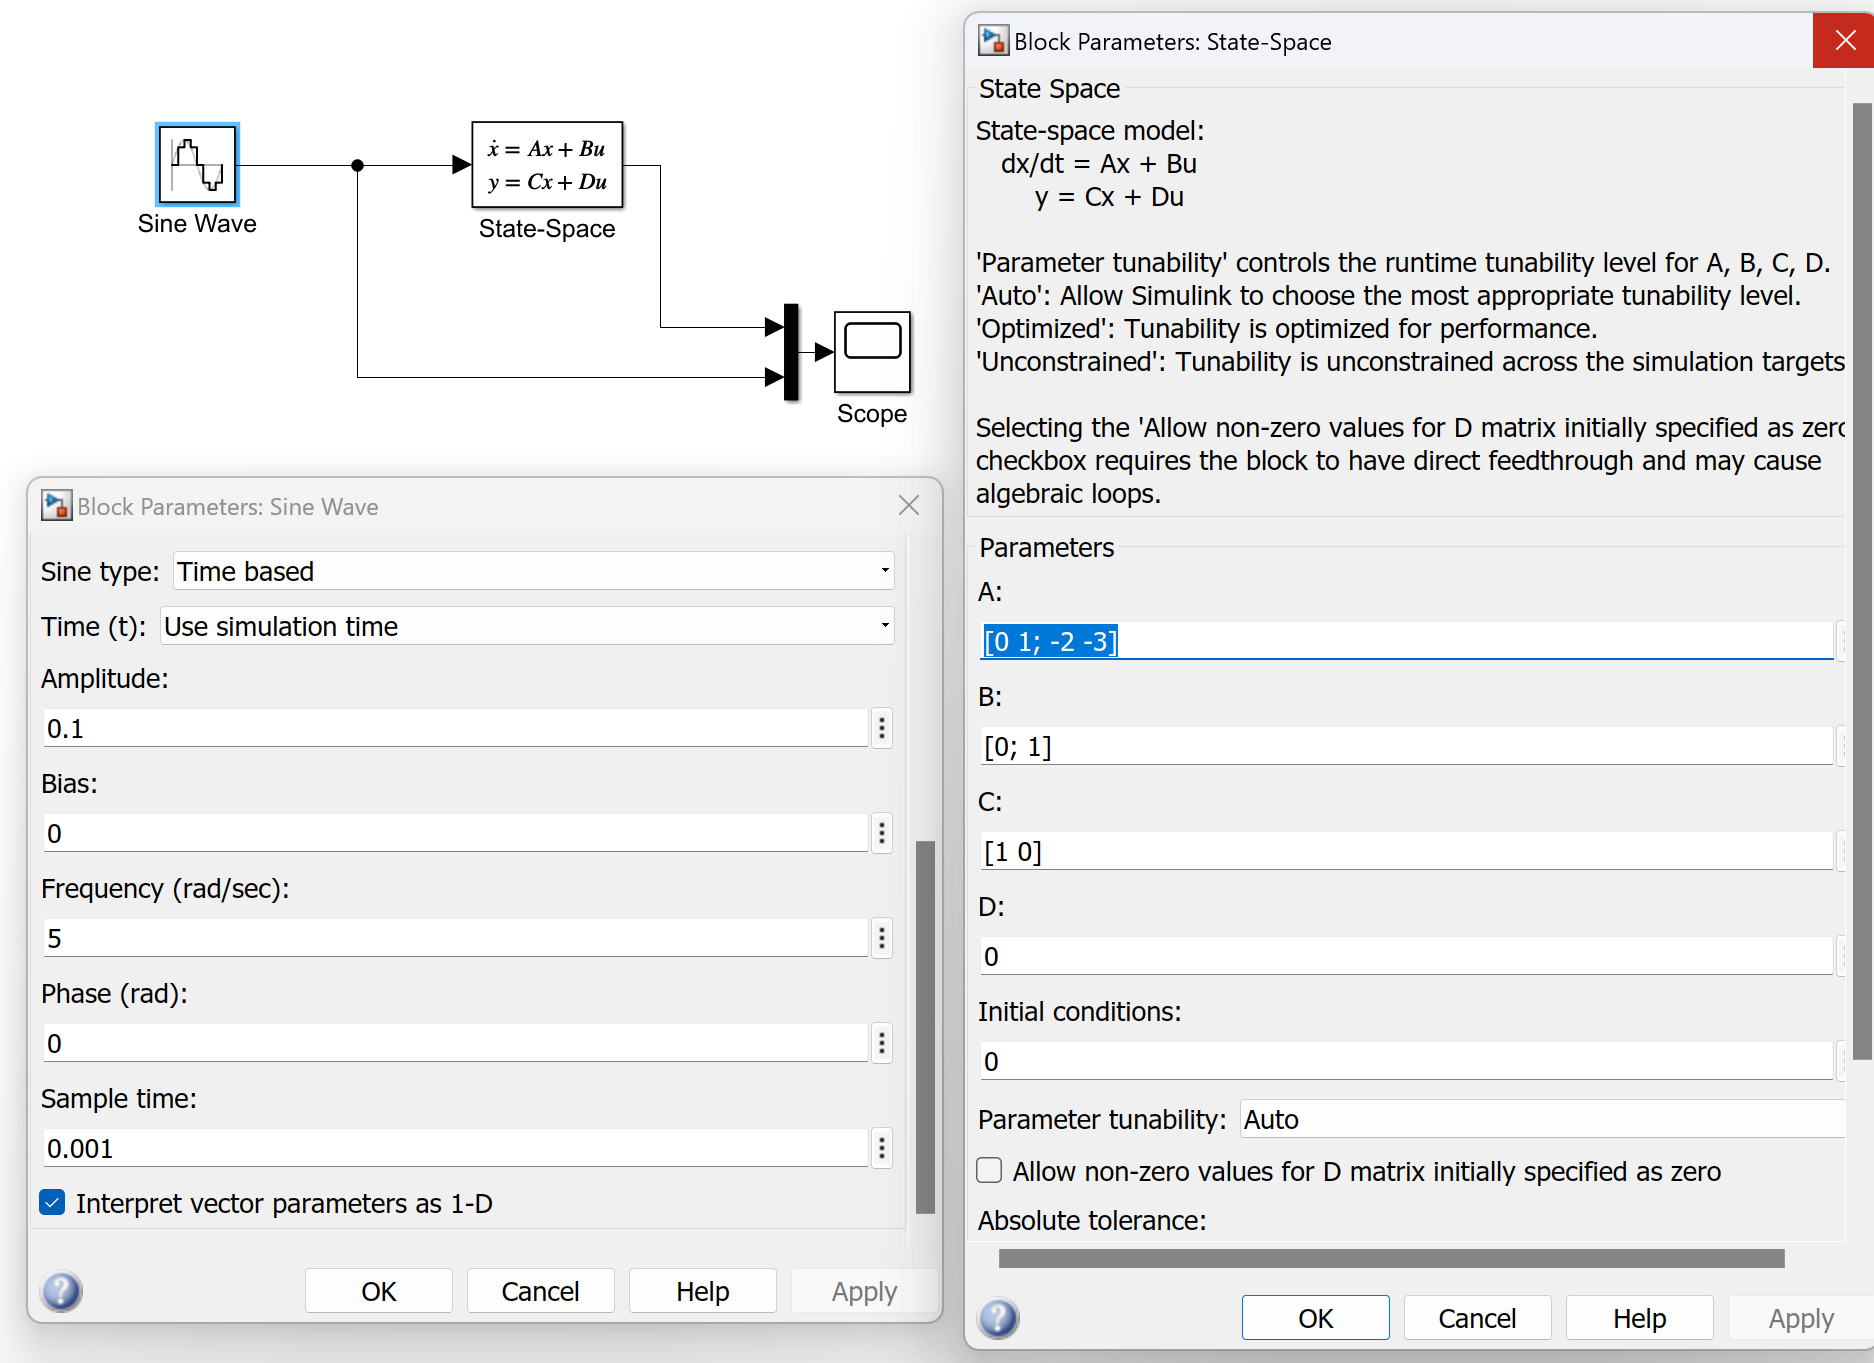

Check the Scope output:

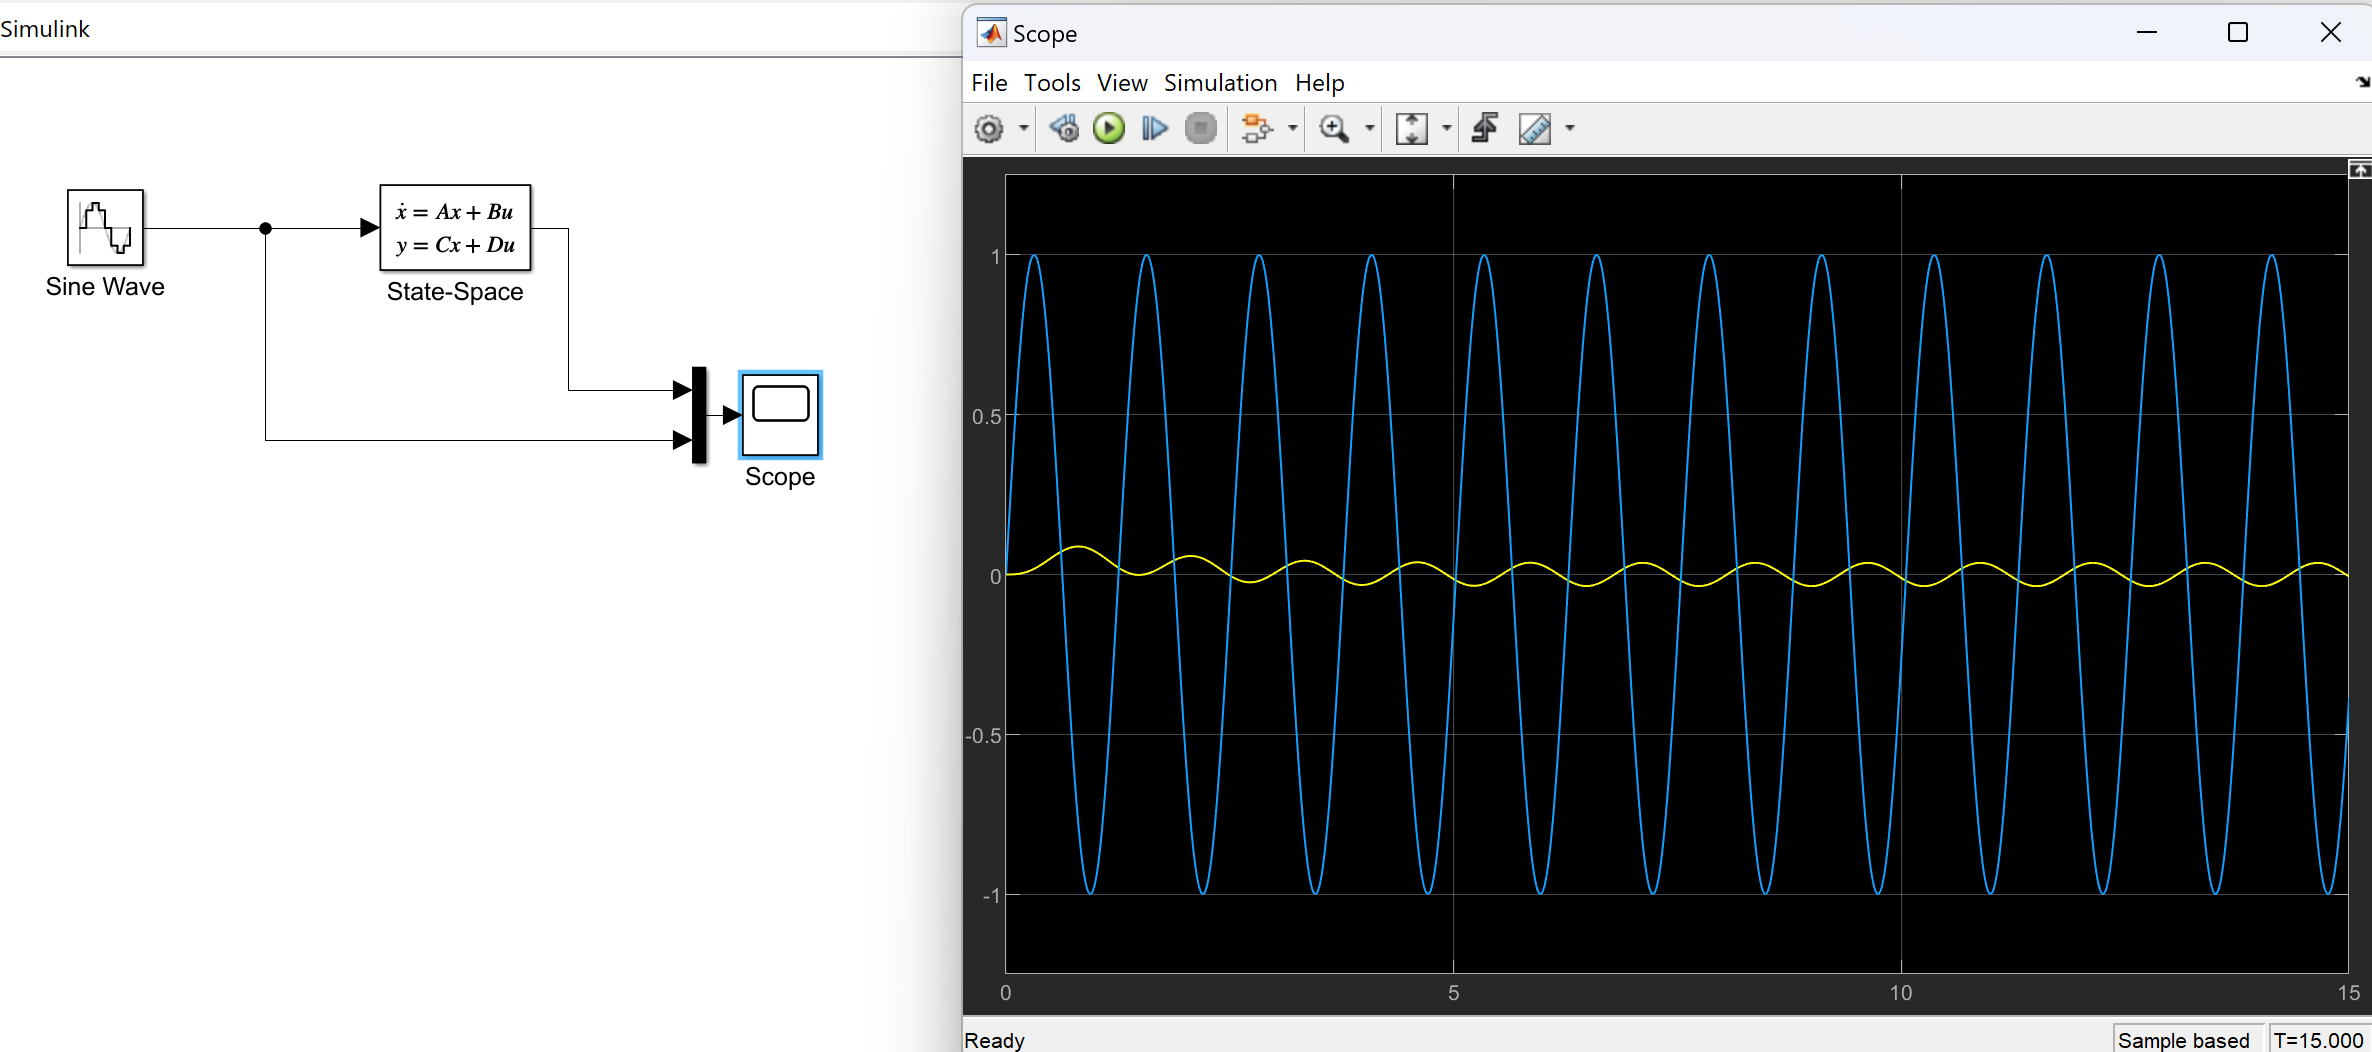

**Part 4:**

Feedback(sys, 1) creates a closed-loop system with unity negative feedback.  

sys_cl = feedback(sys, 1);

Now Lets plot:

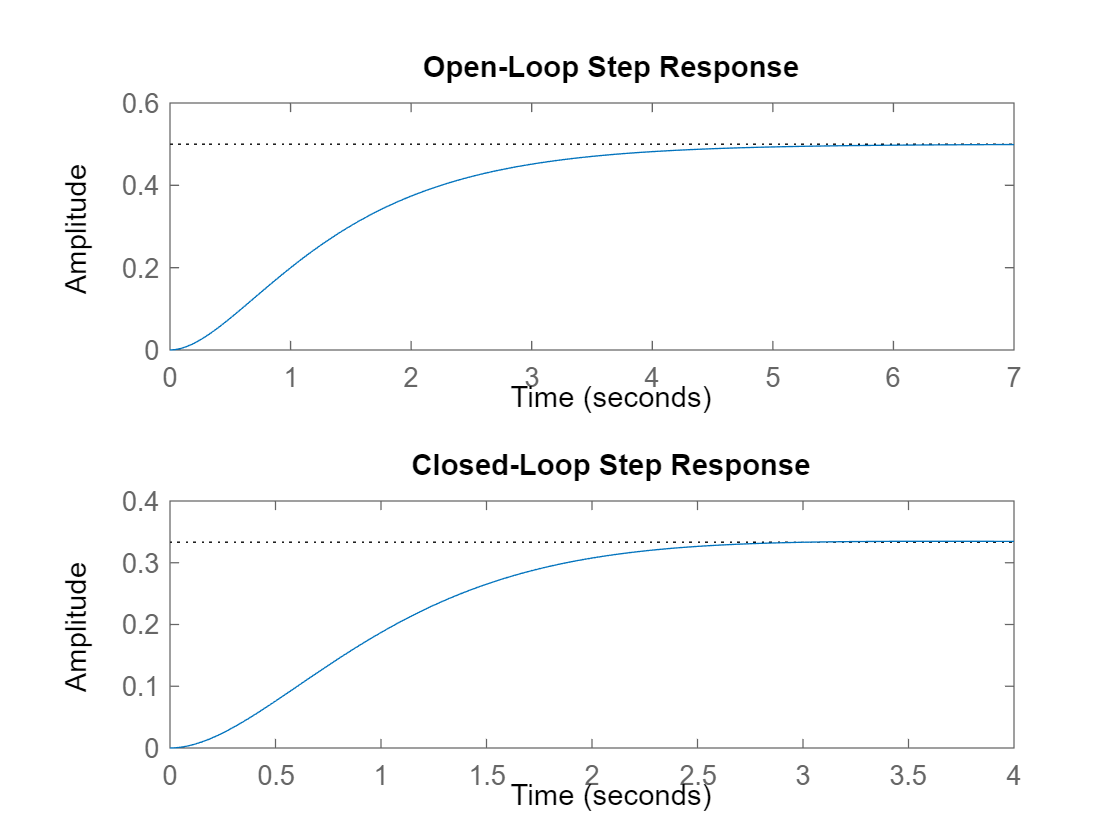

figure;
subplot(2,1,1);
step(sys);
title('Open-Loop Step Response');
subplot(2,1,2);
step(sys_cl);
title('Closed-Loop Step Response');

Lets compare the responses to evaluate how feedback influences stability and response time:

- By using feedback in closed-loop, response time reduces.

- By using feedback in closed-loop, stability incearses.

- By using feedback in closed-loop, Gain reduces as in Trade-off with Stability.

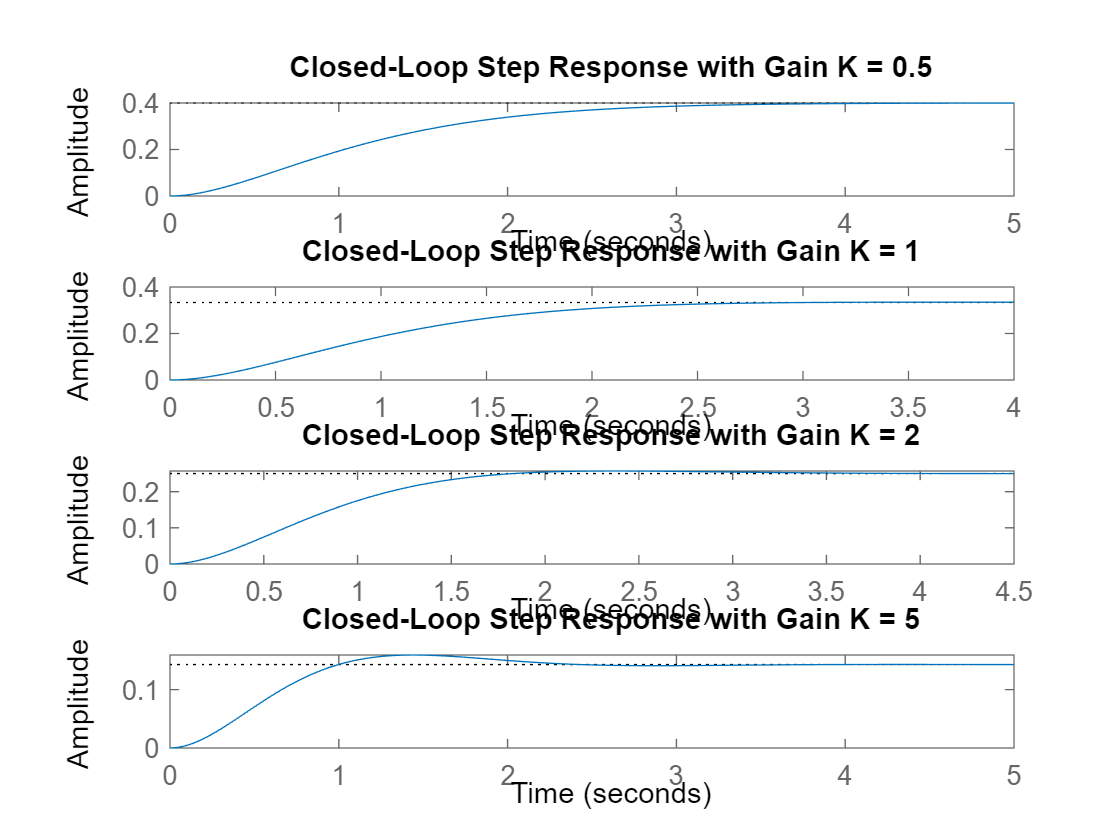

gains = [0.5, 1, 2, 5];
figure;
for i = 1:length(gains)
    sys_cl_k = feedback(sys, gains(i));
    subplot(length(gains), 1, i);
    step(sys_cl_k);
    title(['Closed-Loop Step Response with Gain K = ', num2str(gains(i))]);
end

- As the feedback gain increases, the system's stability and response speed may change. **High gains **could lead to **overshoot or instability**, while **lower gains **might produce a** slower response**.

***Section 7 (*****Symbolic Solution of State-Space Equations using **syms **and **expm() ***): ***

**Initial Code:**

clc; clear; close all;

**Part 1 & 2:**

A = [-1 0; 0 -2]

A =     -1     0
     0    -2


syms t;
Phi = expm(A * t)

$$Phi = \left(\begin{array}{cc} {\mathrm{e}}^{-t} & 0\\ 0 & {\mathrm{e}}^{-2\,t} \end{array}\right)$$

syms x1(t) x2(t);
X = [x1; x2];
eqn = diff(X) == A * X;
homogeneous_sol = dsolve(eqn)

homogeneous_sol = struct with fields:
    x2: C2*exp(-2*t)
    x1: C1*exp(-t)


To Validate:

homogeneous_sol.x1

$$ans = C_{1}\,{\mathrm{e}}^{-t}$$

x0 = [1; 0];
x_h = Phi * x0

$$x\_h = \left(\begin{array}{c} {\mathrm{e}}^{-t}\\ 0 \end{array}\right)$$

So we validated that the symbolic homogeneous solution matches the solution derived using the state transition matrix  .

**Significance of the state transition matrix:**

The state transition matrix $e^{At}
$ $represents how the state evolves over time in response to initial conditions alone (i.e., without any external input). It’s essential for solving the homogeneous part of the system response because it describes the natural response of the system.

**Part 3 & 4 & 5:**

I did some recap and details are in the Comments.

% Define symbolic variables
syms t tau;
x0 = [1; 0];  % Initial condition x(0) = [1; 0]

% Define the matrices A and B
A = [-1 0; 0 -2];
B = [0; 1];

% State transition matrix: Phi(t) = expm(A * t)
Phi = expm(A * t);

% Homogeneous solution: x_h(t) = Phi * x0
x_h = Phi * x0;

% Define the step input u(t) = 1
u = 1;

% Compute the particular solution using the integral with the variation of parameters
% x_p = integral(Phi(t - tau) * B * u, tau, 0, t)

Phi_shifted = subs(Phi, t, t - tau);  % Shifted Phi for the integral
x_p = int(Phi_shifted * B * u, tau, 0, t);

% Complete response: x(t) = x_h(t) + x_p(t)
x_complete = simplify(x_h + x_p);

% Display the symbolic expressions for verification
disp('Homogeneous solution, x_h(t):');

Homogeneous solution, x_h(t):


disp(x_h);

$$\left(\begin{array}{c} {\mathrm{e}}^{-t}\\ 0 \end{array}\right)$$

disp('Particular solution, x_p(t):');

Particular solution, x_p(t):


disp(x_p);

$$\left(\begin{array}{c} 0\\ \frac{1}{2}-\frac{{\mathrm{e}}^{-2\,t}}{2} \end{array}\right)$$

disp('Complete solution, x(t):');

Complete solution, x(t):


disp(x_complete);

$$\left(\begin{array}{c} {\mathrm{e}}^{-t}\\ \frac{1}{2}-\frac{{\mathrm{e}}^{-2\,t}}{2} \end{array}\right)$$

**Part 5:**

After solving for symbolic / Numerical solution, we plot both of them.

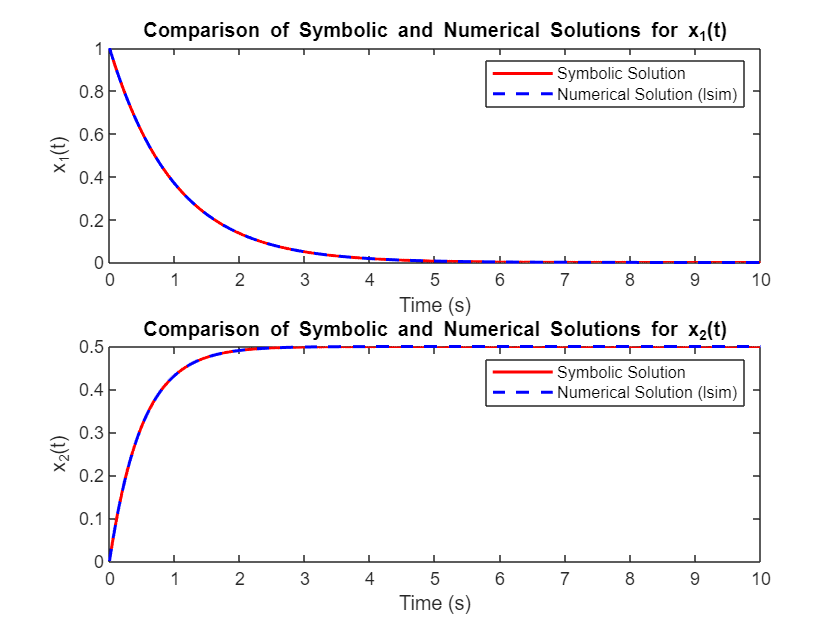

% Substitute symbolic time variable t with a numeric vector for plotting
t_span = 0:0.01:10;  % Time range for the plot
x_complete_numeric = double(subs(x_complete, t, t_span));

% Numerical simulation using lsim for comparison
sys = ss(A, B, eye(2), 0);  % State-space system with identity output matrix
u_step = ones(size(t_span));  % Step input
[y, t_out, x_lsim] = lsim(sys, u_step, t_span, x0);  % Specify x0 as initial condition

% Plot both the symbolic and numerical solutions for comparison
figure;
subplot(2,1,1);
plot(t_span, x_complete_numeric(1,:), 'r', 'LineWidth', 1.5); hold on;
plot(t_out, x_lsim(:,1), 'b--', 'LineWidth', 1.5);
title('Comparison of Symbolic and Numerical Solutions for x_1(t)');
xlabel('Time (s)');
ylabel('x_1(t)');
legend('Symbolic Solution', 'Numerical Solution (lsim)');

subplot(2,1,2);
plot(t_span, x_complete_numeric(2,:), 'r', 'LineWidth', 1.5); hold on;
plot(t_out, x_lsim(:,2), 'b--', 'LineWidth', 1.5);
title('Comparison of Symbolic and Numerical Solutions for x_2(t)');
xlabel('Time (s)');
ylabel('x_2(t)');
legend('Symbolic Solution', 'Numerical Solution (lsim)');

As we can observe Symbolic Solution and Numerical one perfectly match.

**Part 6:**

When we change the input from a step function $u\left(t\right)=1$ to a ramp function $u\left(t\right)=t$, the behavior of the system's response changes significantly. A ramp input causes the system states to evolve differently due to the continuous increase in input over time.

**Analysis:**

**            1. New Input Definition**:

- For a ramp input, $u(t) = 1
$, the control input continuously grows over time, which will influence both states $x_1(t)$ and $x_2(t)
$ in a cumulative manner. This is in contrast to a step input where $u(t)$ is constant, leading to a steady-state response after the transient phase.

**            2. Particular Solution Adjustment**:

- With $u(t) = 1
$, we modify the particular solution computation. The particular solution becomes: 

                    
$$x_p(t) = \int_0^t \Phi(t - \tau) B \cdot \tau \, d\tau$$
 

**            3. Complete Solution with Ramp Input**:

- The complete solution will again be the sum of the homogeneous solution $x_h(t)$and the new particular solution $x_p(t)$. The ramp input results in a non-zero growth component in the state $x_2(t)$ (and possibly in $x_1(t)$ depending on the effect of $A
$ and $B$).

% Define symbolic variables and initial conditions
syms t tau;
x0 = [1; 0];  % Initial condition x(0) = [1; 0]

% Define the matrices A and B
A = [-1 0; 0 -2];
B = [0; 1];

% State transition matrix: Phi(t) = expm(A * t)
Phi = expm(A * t);

% Homogeneous solution: x_h(t) = Phi * x0
x_h = Phi * x0;

% Ramp input u(t) = t
u = t;

% Compute the particular solution with ramp input using the integral

% x_p = integral(Phi(t - tau) * B * tau, tau, 0, t)
Phi_shifted = subs(Phi, t, t - tau);  % Shifted Phi for the integral
x_p = int(Phi_shifted * B * tau, tau, 0, t);

% Complete response: x(t) = x_h(t) + x_p(t)
x_complete_ramp = simplify(x_h + x_p);

% Display the symbolic expressions for verification
disp('Homogeneous solution, x_h(t):');

Homogeneous solution, x_h(t):


disp(x_h);

$$\left(\begin{array}{c} {\mathrm{e}}^{-t}\\ 0 \end{array}\right)$$

disp('Particular solution with ramp input, x_p(t):');

Particular solution with ramp input, x_p(t):


disp(x_p);

$$\left(\begin{array}{c} 0\\ \frac{t}{2}+\frac{{\mathrm{e}}^{-2\,t}}{4}-\frac{1}{4} \end{array}\right)$$

disp('Complete solution with ramp input, x(t):');

Complete solution with ramp input, x(t):


disp(x_complete_ramp);

$$\left(\begin{array}{c} {\mathrm{e}}^{-t}\\ \frac{t}{2}+\frac{{\mathrm{e}}^{-2\,t}}{4}-\frac{1}{4} \end{array}\right)$$

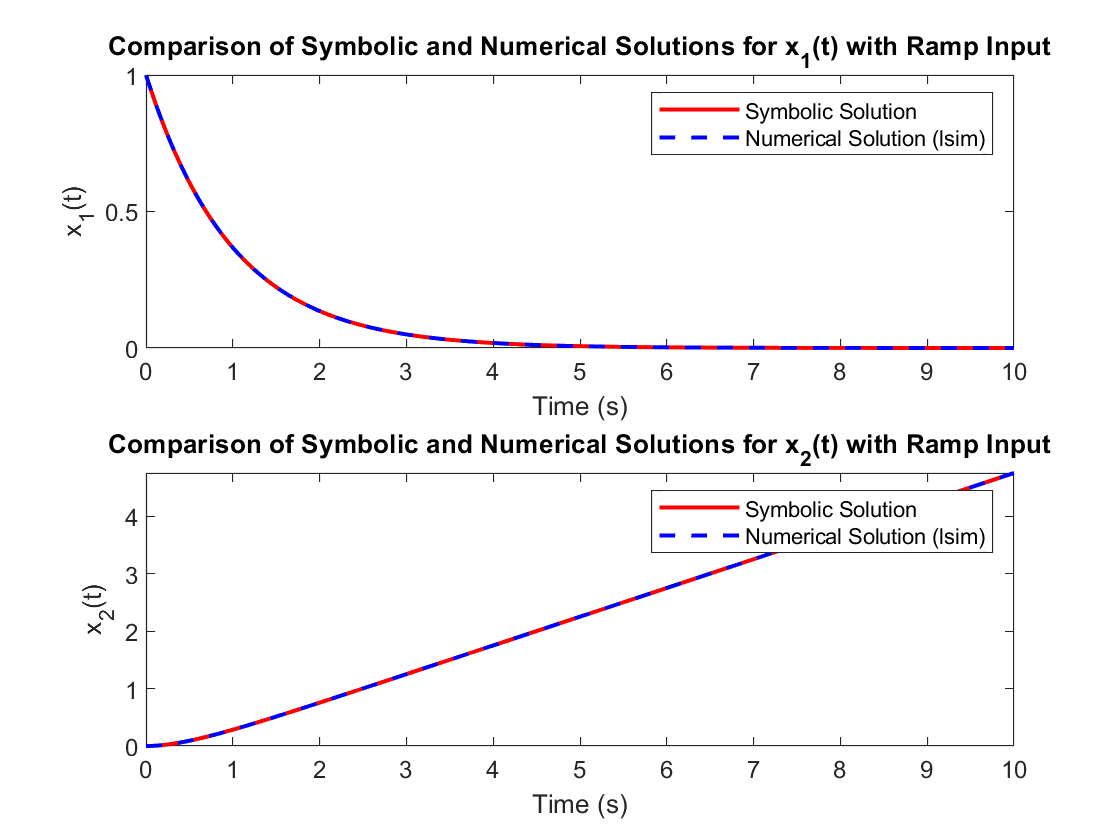


% Substitute symbolic time variable t with a numeric vector for plotting
t_span = 0:0.01:10;  % Time range for the plot
x_complete_numeric_ramp = double(subs(x_complete_ramp, t, t_span));

% Numerical validation with lsim for ramp input
u_ramp = t_span;  % Ramp input
sys = ss(A, B, eye(2), 0);  % State-space system with identity output matrix
[y_ramp, t_out, x_lsim_ramp] = lsim(sys, u_ramp, t_span, x0);  % Specify x0 as initial condition

% Plot both the symbolic and numerical solutions for comparison
figure;
subplot(2,1,1);
plot(t_span, x_complete_numeric_ramp(1,:), 'r', 'LineWidth', 1.5); hold on;
plot(t_out, x_lsim_ramp(:,1), 'b--', 'LineWidth', 1.5);
title('Comparison of Symbolic and Numerical Solutions for x_1(t) with Ramp Input');
xlabel('Time (s)');
ylabel('x_1(t)');
legend('Symbolic Solution', 'Numerical Solution (lsim)');

subplot(2,1,2);
plot(t_span, x_complete_numeric_ramp(2,:), 'r', 'LineWidth', 1.5); hold on;
plot(t_out, x_lsim_ramp(:,2), 'b--', 'LineWidth', 1.5);
title('Comparison of Symbolic and Numerical Solutions for x_2(t) with Ramp Input');
xlabel('Time (s)');
ylabel('x_2(t)');
legend('Symbolic Solution', 'Numerical Solution (lsim)');

**Results and Analysis:**

- **   Impact on **$x_1(t)$:

- For $x_1(t)$, if the effect of $B$ on this state is minimal (since B = [0; 1], directly impacting only $x_2(t)$), the growth due to the ramp input is limited.

- $x_1(t)$still decays based on the initial condition, but the influence of the ramp input on this component is expected to be minimal.

**          2.    Impact on **$x_2(t)$:

- The ramp input has a direct and growing influence on $x_2(t)$because B impacts this state directly.

- $x_2(t)$ will not settle to a steady state as it did for a step input; instead, it will continuously grow over time due to the persistent increase in input.

***Section 8 (*****Step Response and State-Space Canonical Forms** ***): ***

**General Steps:**

- **State-Space Conversion:** Use `ss()` to convert the transfer function into state-space form.

- **Canonical Form Transformation:** Use `canon(sys, 'companion')` to get the controllable canonical form and ... .

- **Step Response Simulation:** Compute the values of each function at the time points and plot them.

- **Controllability and Observability Check: **Use `step()` or `lsim()` to compare the step responses of the original system and both canonical forms.

- **Simulink Validation: **Build a Simulink model with state-space or transfer function blocks and validate the step response against MATLAB results.

**Initial Code:**

clc; clear; close all;

**Part (I) State-Space Conversion:**

- **Transfer Function to State-Space Conversion**: Use the `ss()` function in MATLAB to convert the transfer function G(s) into state-space form.

% Define the transfer function
num = 5;
den = [1 4 5];
G = tf(num, den);


sys =
 
  A = 
         x1    x2
   x1    -4  -2.5
   x2     2     0
 
  B = 
       u1
   x1   2
   x2   0
 
  C = 
         x1    x2
   y1     0  1.25
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% Convert to state-space form
sys = ss(G)

**        2. Physical Meaning of State-Space Matrices**:

- The state-space model is represented as: x˙=Ax+Bu\dot{x} = Ax + Bux˙=Ax+Buy=Cx+Duy = Cx + Duy=Cx+Du

- **A matrix**: Describes the dynamics of the system's states. Each entry represents how one state affects the rate of change of another.

- **B matrix**: Represents the input's influence on each state.

- **C matrix**: Relates the states to the output, mapping internal states to the system output.

- **D matrix**: Directly maps the input to the output. In many physical systems, this term is zero if there is no direct transmission path.

**Part (II) Canonical Form Transformation:**

- **Convert to Controllable and Observable Canonical Forms**:

% Controllable Canonical Form
sys_ctrb = canon(sys, 'companion')

sys_ctrb =
 
  A = 
       x1  x2
   x1   0  -5
   x2   1  -4
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% Observable Canonical Form
% % % % sys_obsv = canon(sys, 'observable')


% Get controllable modal form (Instead of 'observable')
sys_obsv = canon(sys, 'modal')

sys_obsv =
 
  A = 
       x1  x2
   x1  -2   1
   x2  -1  -2
 
  B = 
           u1
   x1   1.499
   x2  -5.646
 
  C = 
            x1       x2
   y1  -0.8273  -0.2197
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



**Verification by Step Response**:

To confirm that the canonical forms match the original system, compare their step responses.

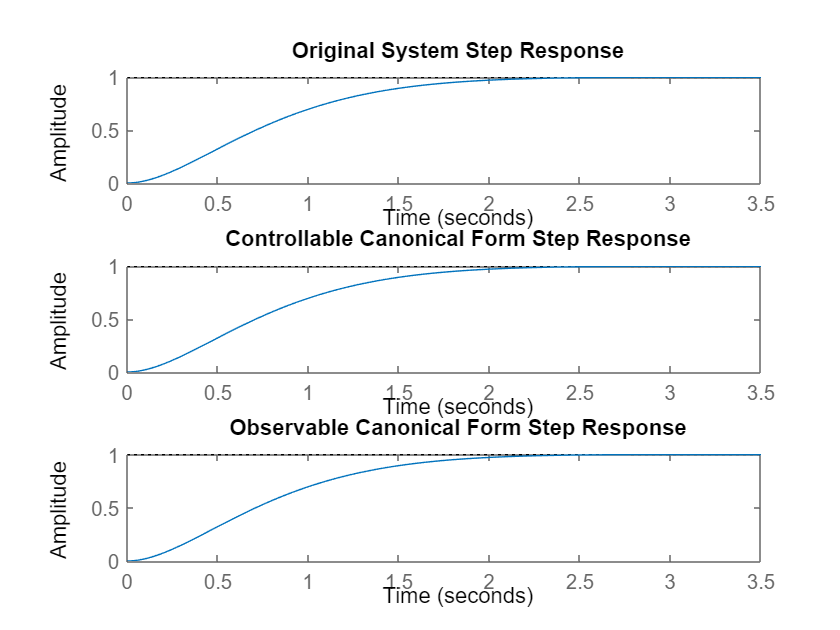

% Compare step responses
figure;
subplot(3,1,1);
step(sys);
title('Original System Step Response');

subplot(3,1,2);
step(sys_ctrb);
title('Controllable Canonical Form Step Response');

subplot(3,1,3);
step(sys_obsv);
title('Observable Canonical Form Step Response');

**Controllability and Observability Matrices**:

- **Controllability Matrix** $C_{\text{ctrb}}$�: Calculate and check its rank to confirm the system's controllability.

C_ctrb = ctrb(sys_ctrb.A, sys_ctrb.B)

C_ctrb =      1     0
     0     1


rank_C_ctrb = rank(C_ctrb)

rank_C_ctrb = 2

- **Observability Matrix** $O_{\text{obsv}}$�: Similarly, calculate and check its rank for observability.

O_obsv = obsv(sys_obsv.A, sys_obsv.C)

O_obsv =    -0.8273   -0.2197
    1.8742   -0.3879


rank_O_obsv = rank(O_obsv)

rank_O_obsv = 2

**Part (III) Step Response Simulation:**

- **Simulate the Step Response**:

- Use `lsim()` to simulate the system's response to a unit step input for each form.

I coded it below.

- Compare the responses by analyzing rise time, settling time, and overshoot.

They are perfectly aligned, so rise time, settling time, and overshoot are the same. It has a rise time/settling time of around 2s, it doesn't have any overshoot.

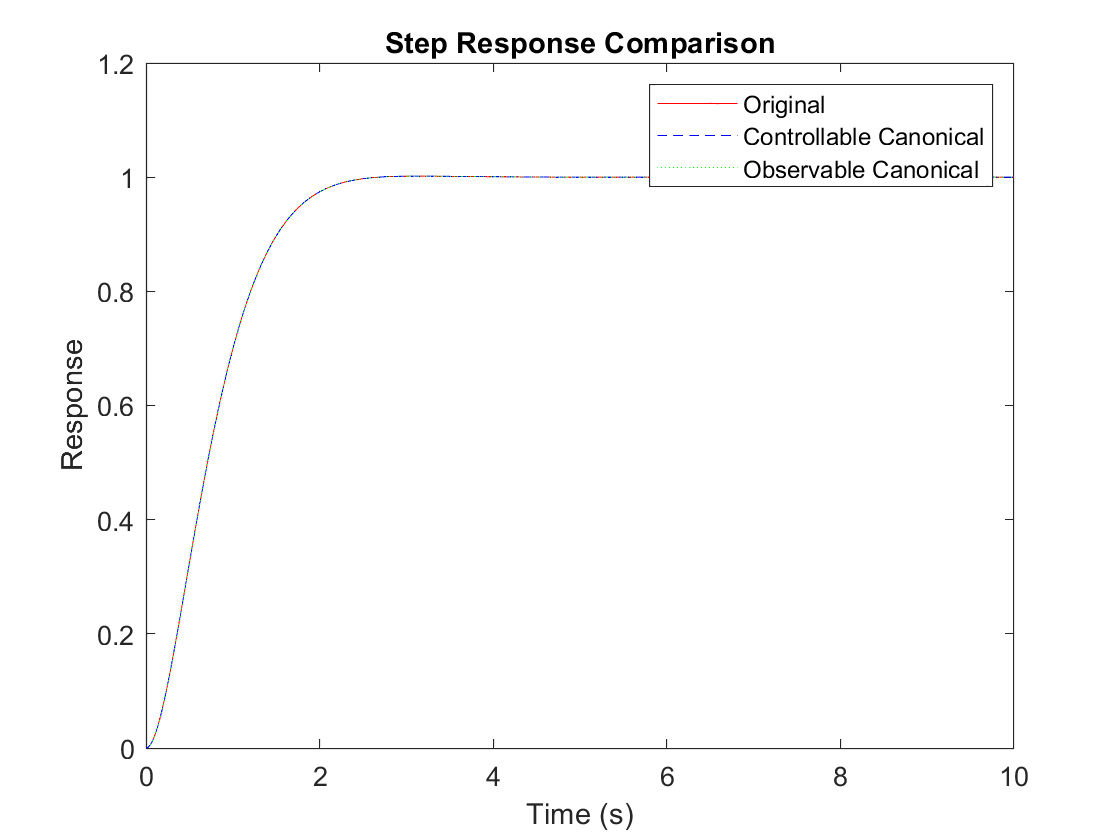

% Define time vector for simulation
t = 0:0.01:10;
u = ones(size(t)); % Step input

% Simulate responses
[y_orig, ~] = lsim(sys, u, t);
[y_ctrb, ~] = lsim(sys_ctrb, u, t);
[y_obsv, ~] = lsim(sys_obsv, u, t);

% Plot step responses
figure;
plot(t, y_orig, 'r', t, y_ctrb, 'b--', t, y_obsv, 'g:');
legend('Original', 'Controllable Canonical', 'Observable Canonical');
title('Step Response Comparison');
xlabel('Time (s)');
ylabel('Response');

**Explanation**: Despite the different state-space representations, the step responses should be identical because each form represents the same transfer function, which determines the input-output behavior. Amy system can have many different state-space representations but the same responses and a unit transfer function.

***Section 9 (*****Nonlinear System Linearization using Symbolic Math Toolbox** ***): ***

**General Steps:**

- **Identify Equilibrium:** Set $\(\dot{x}_1 = 0\)$ and $\(\dot{x}_2 = 0\) $ to find the equilibrium point.

- **Linearize the System:** Use symbolic differentiation to compute the Jacobian matrices $\(A\)$ (with respect to states) and $\(B\) $ (with respect to input) around the equilibrium.

- **Form State-Space Model:** Substitute the equilibrium values into $\(A\)$ and $\(B\)$ to get $\(A_{eq}\)$ and $\(B_{eq}\)$, then define $\(C\)$ and $\(D\)$ for output.

- **Stability Analysis: **Calculate the eigenvalues of $\(A_{eq}\)$ to assess stability.

- **Simulate Responses: **Use a step input in Simulink for both nonlinear and linearized models, comparing outputs for different input magnitudes to see how well the linear approximation holds.

**Initial Code:**

clc; clear; close all;

**Part I: Linearization around the Equilibrium Point**

**1. Equilibrium Point**:

- The system is at equilibrium when $\dot{x}_1 = 0$ and $\dot{x}_2 = 0$.

- From the given equations: $x_1 = 0, \quad x_2 = 0, \quad u = 0$

- So, we will linearize the system around this equilibrium.

**2. Symbolic Definition and Jacobians**:

Lets define the system symbolically in MATLAB:

syms x1 x2 u
f = [x2; -sin(x1) + u]

$$f = \left(\begin{array}{c} x_{2}\\ u-\sin\left(x_{1}\right) \end{array}\right)$$

Now lets Compute the Jacobian matrices with respect to x and u:

A = jacobian(f, [x1, x2])

$$A = \left(\begin{array}{cc} 0 & 1\\ -\cos\left(x_{1}\right) & 0 \end{array}\right)$$

B = jacobian(f, u)

$$B = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

**3. Evaluate Jacobians at Equilibrium**:

Substitute $x_1 = 0$, $x_2 = 0$, and $u = 0$ to get $A_{eq}$� and $B_{eq}$:

A_eq = subs(A, {x1, x2, u}, {0, 0, 0})

$$A\_eq = \left(\begin{array}{cc} 0 & 1\\ -1 & 0 \end{array}\right)$$

B_eq = subs(B, {x1, x2, u}, {0, 0, 0})

$$B\_eq = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

**Part II: State-Space Representation**

- **State-Space Model**:

The linearized system representation is $\dot{x} = Ax + Bu$. Define the output as $y = x_1$�, so set C and D:

C = [1 0]; % since y = x1
D = 0;

- **MATLAB Representation**:

Convert $A_{eq}$� and $B_{eq}$� to numeric form and define the linearized system:

sys_lin = ss(double(A_eq), double(B_eq), C, D)

sys_lin =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1   0
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



**Stability Analysis**:

- Compute eigenvalues of $A_{eq}$� to determine system stability:

eigenvalues = eig(A_eq)

$$eigenvalues = \left(\begin{array}{c} -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

- Interpret the eigenvalues: if all eigenvalues have negative real parts, the system is stable around the equilibrium.

As we can see from the eigenvalues vector of Matix A_eq,  the real part of both elementsare zero, So we have **Marginal Stability.**

**Part III: Simulation in Simulink**

Model I designed:

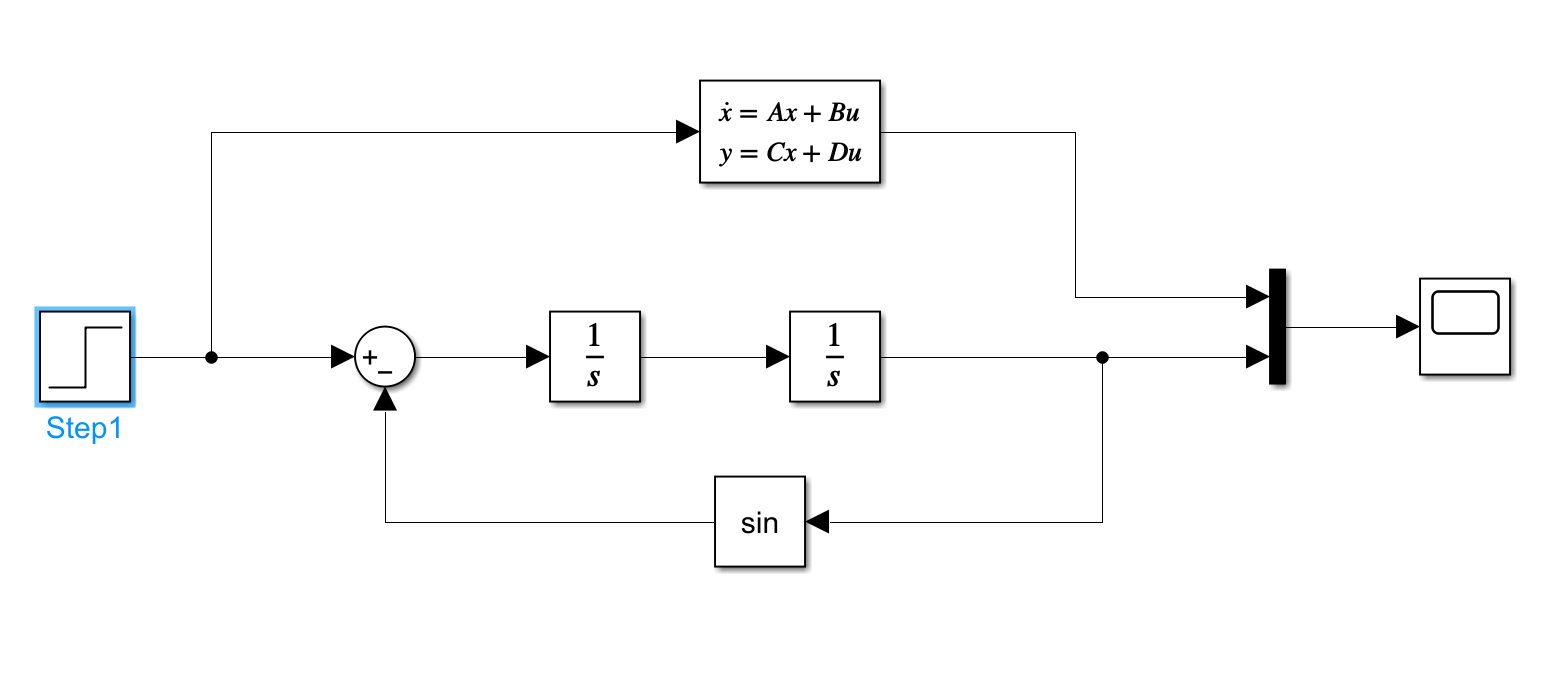�

For $u(t) = 0.1
$:

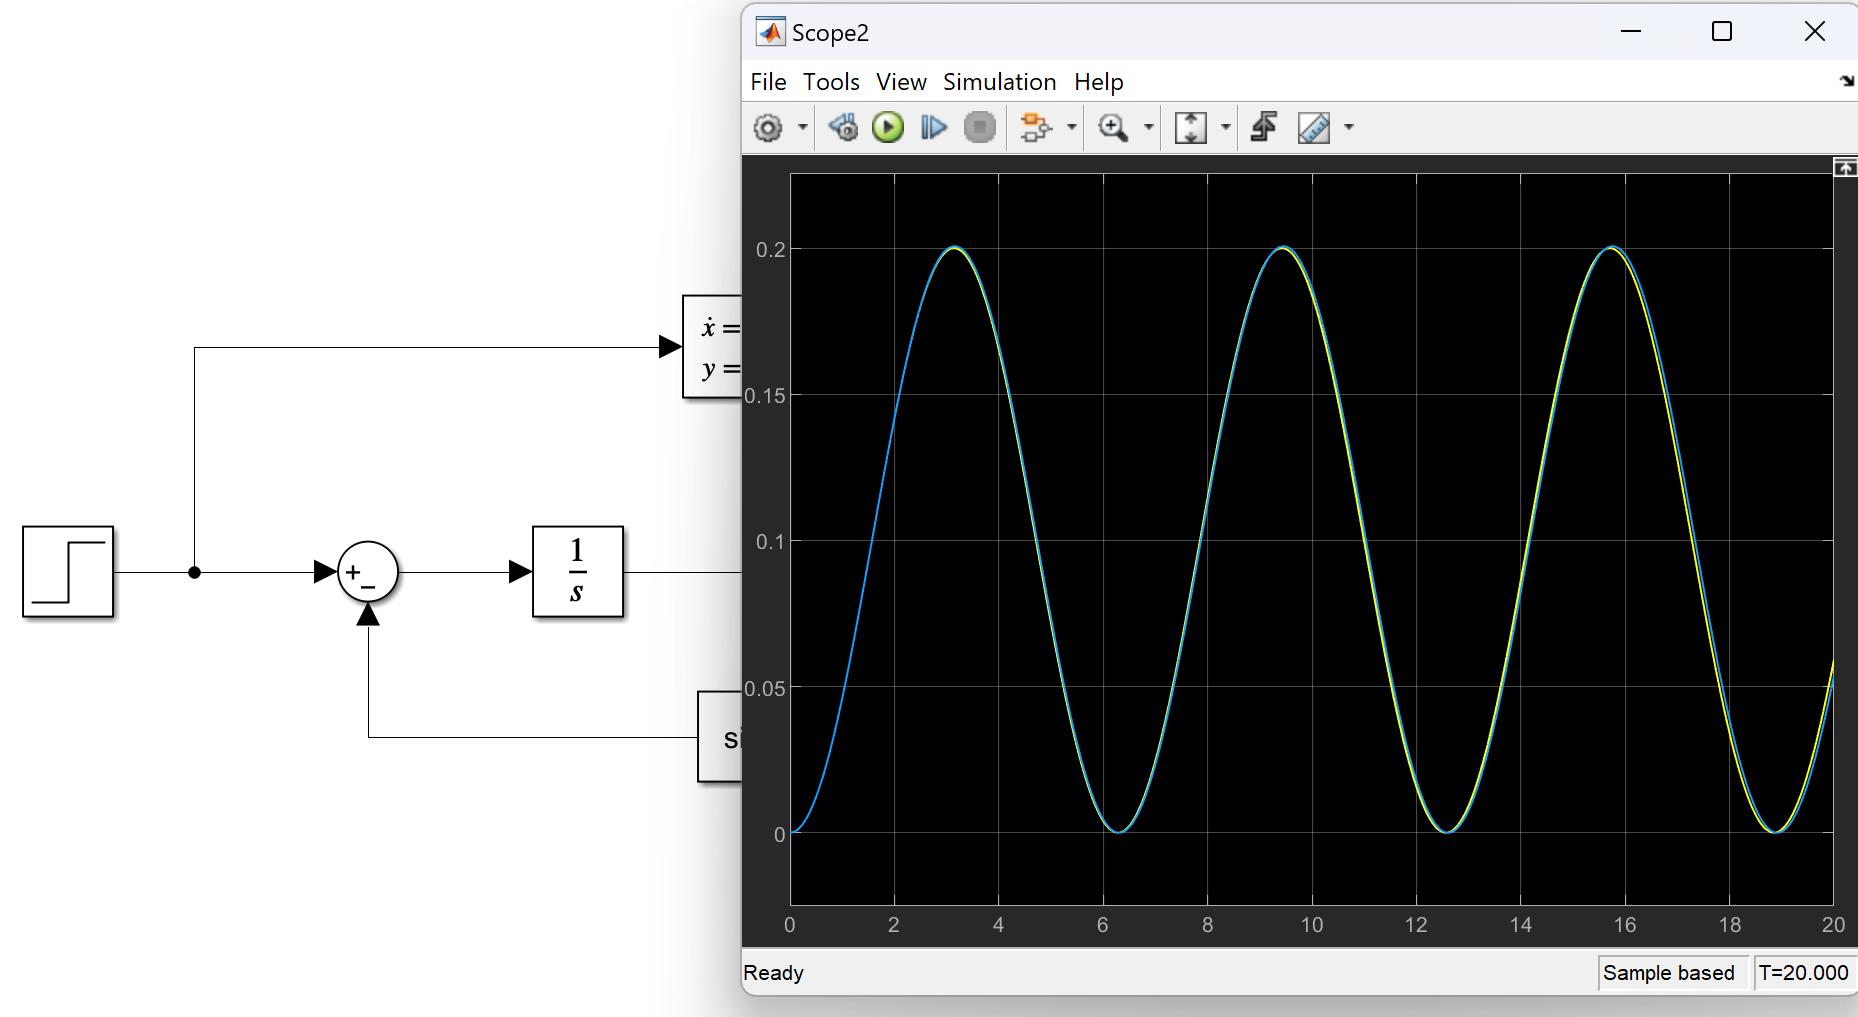

For $u(t)=
$1:

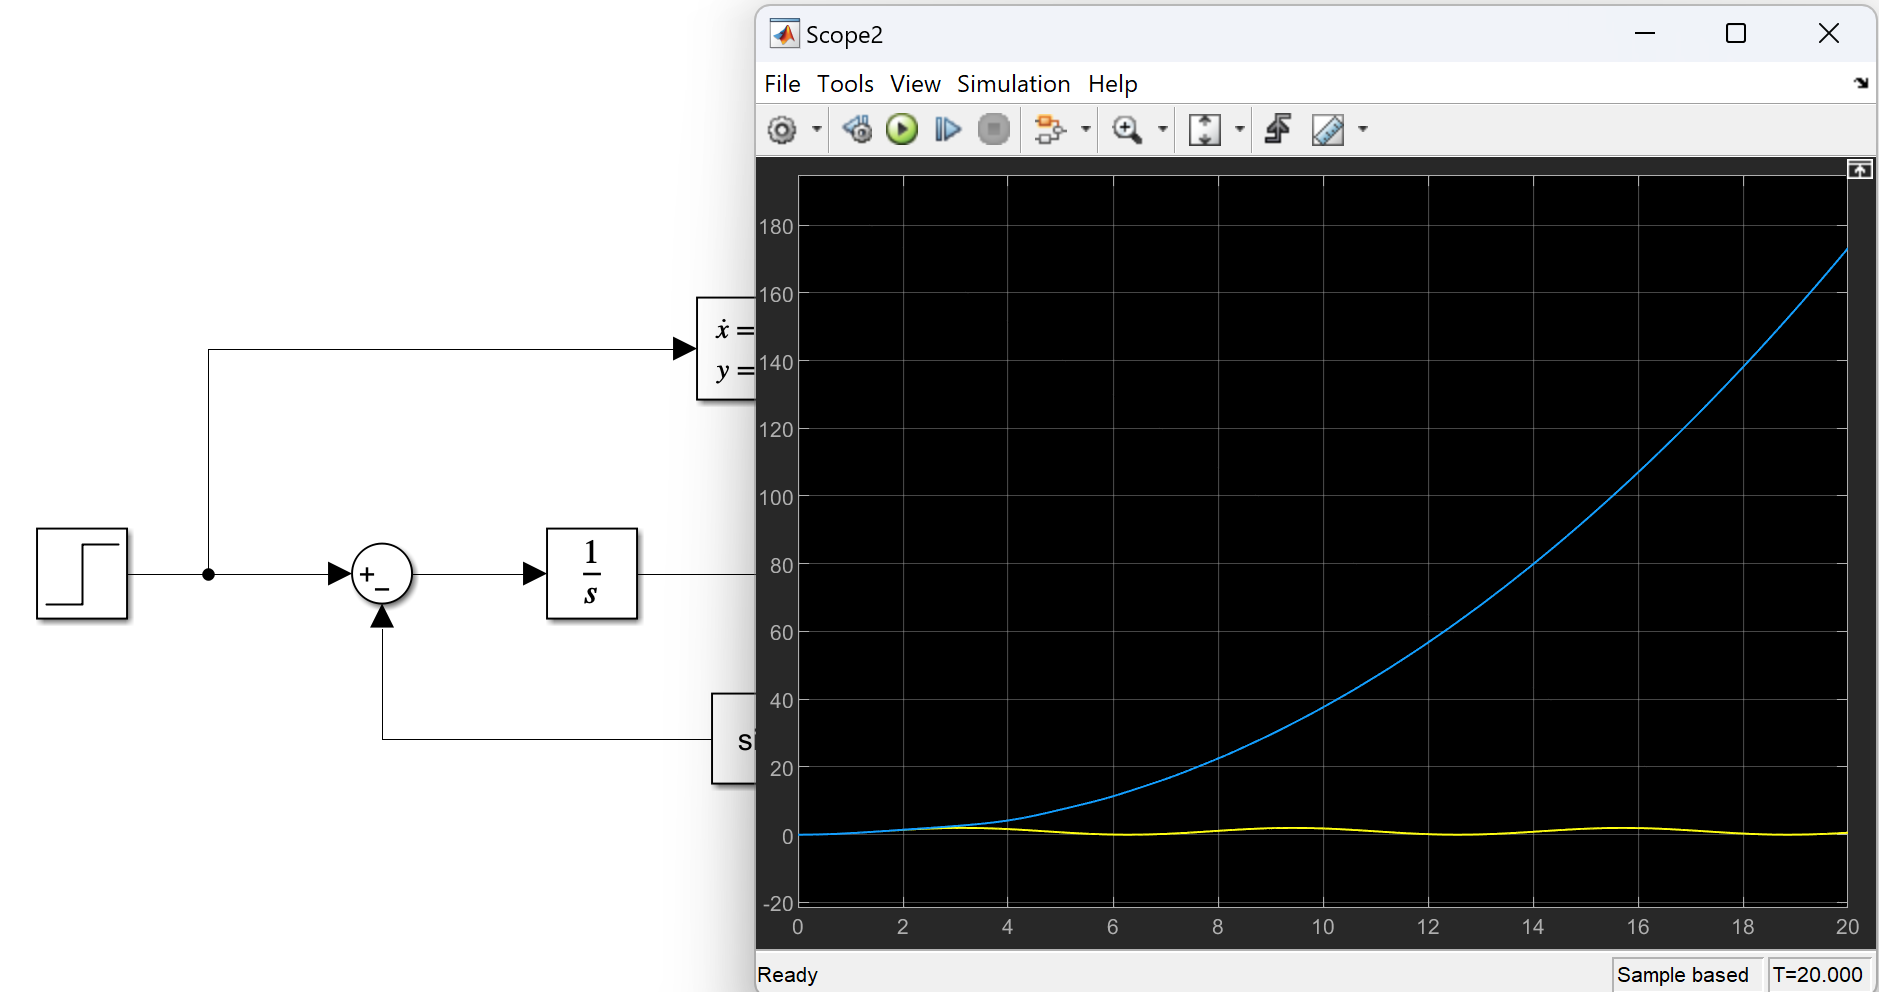

For $u(t)=
$5:

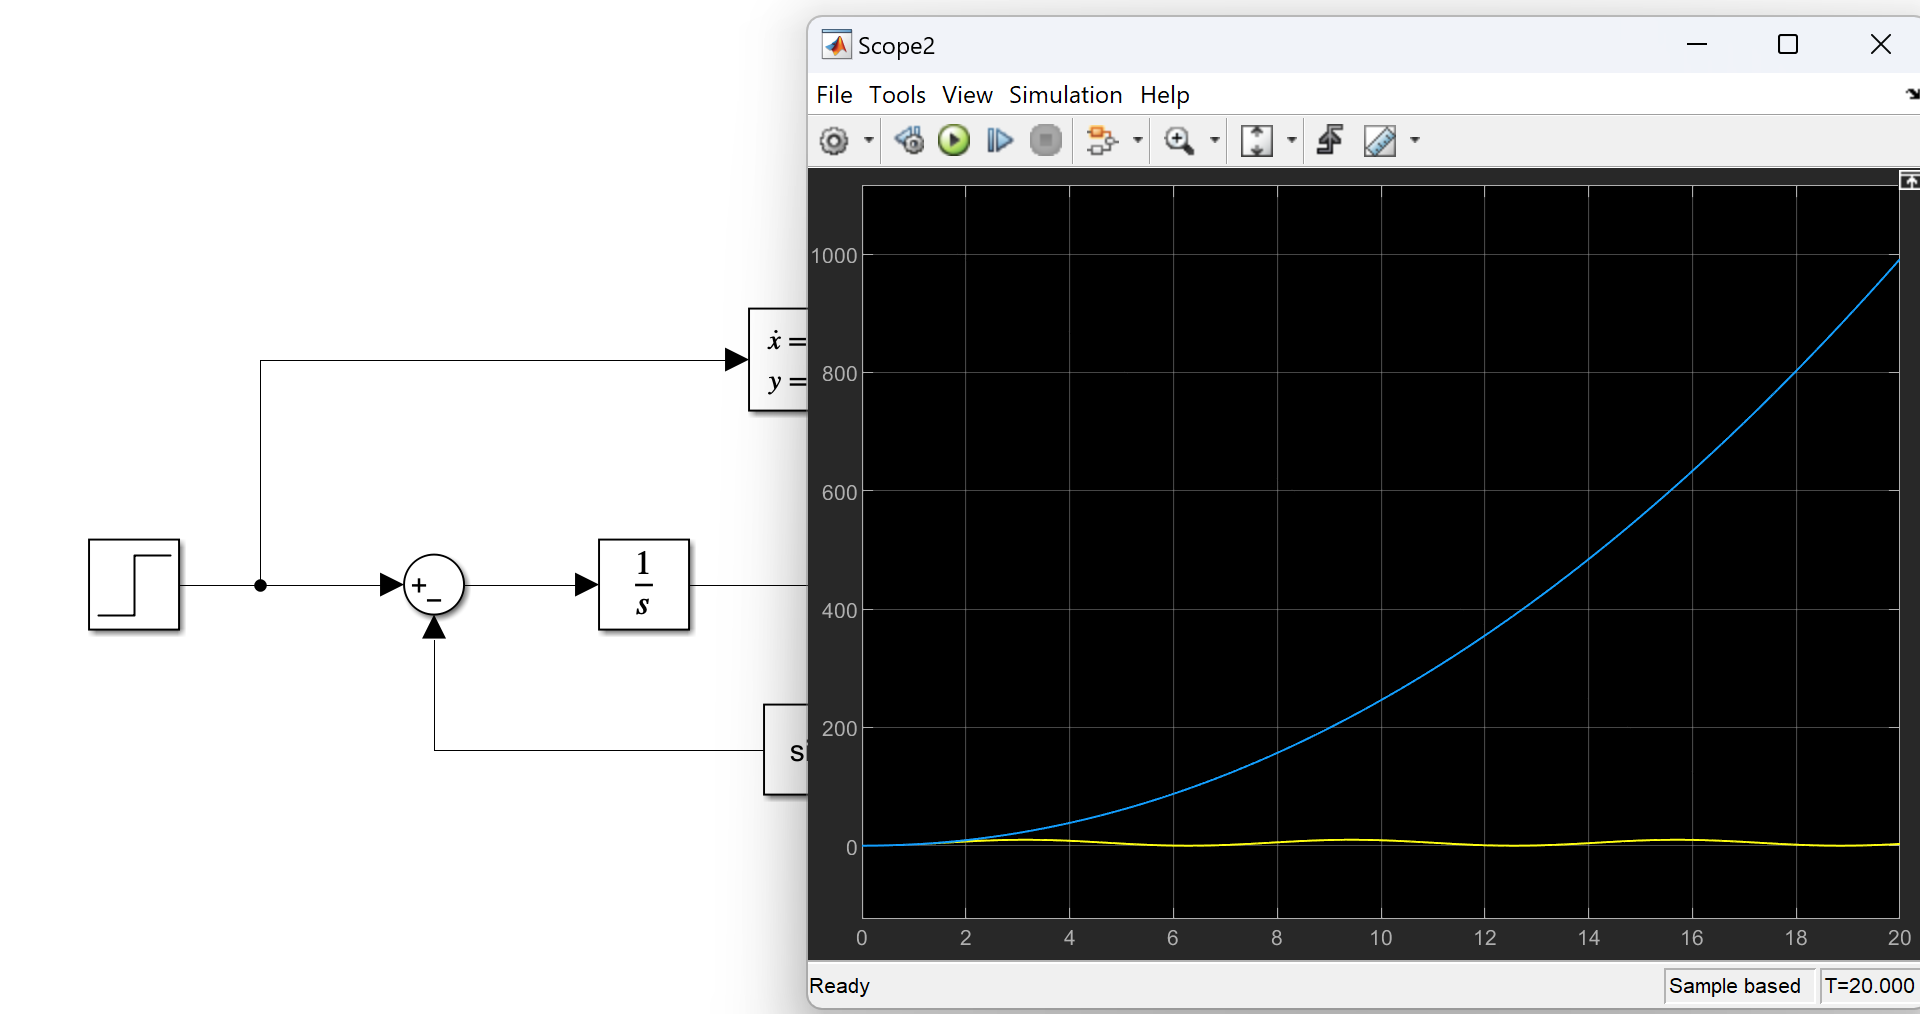

From the graphs, we observe that for smaller step input values, the response of the nonlinear system closely matches that of the linearized system. However, as the step input increases, the nonlinear system's frequency decreases, and its peak response rises. When $\( u(t) \)$ reaches 0.6 to 0.7, the nonlinear system's response begins to show signs of additional harmonic frequencies. With a further increase in $\( u(t) \)$ from 0.72 to 0.73, the output transitions from a bounded to an unbounded response. Beyond 0.73, the nonlinear system's output diverges.

Initial Condition= 1:

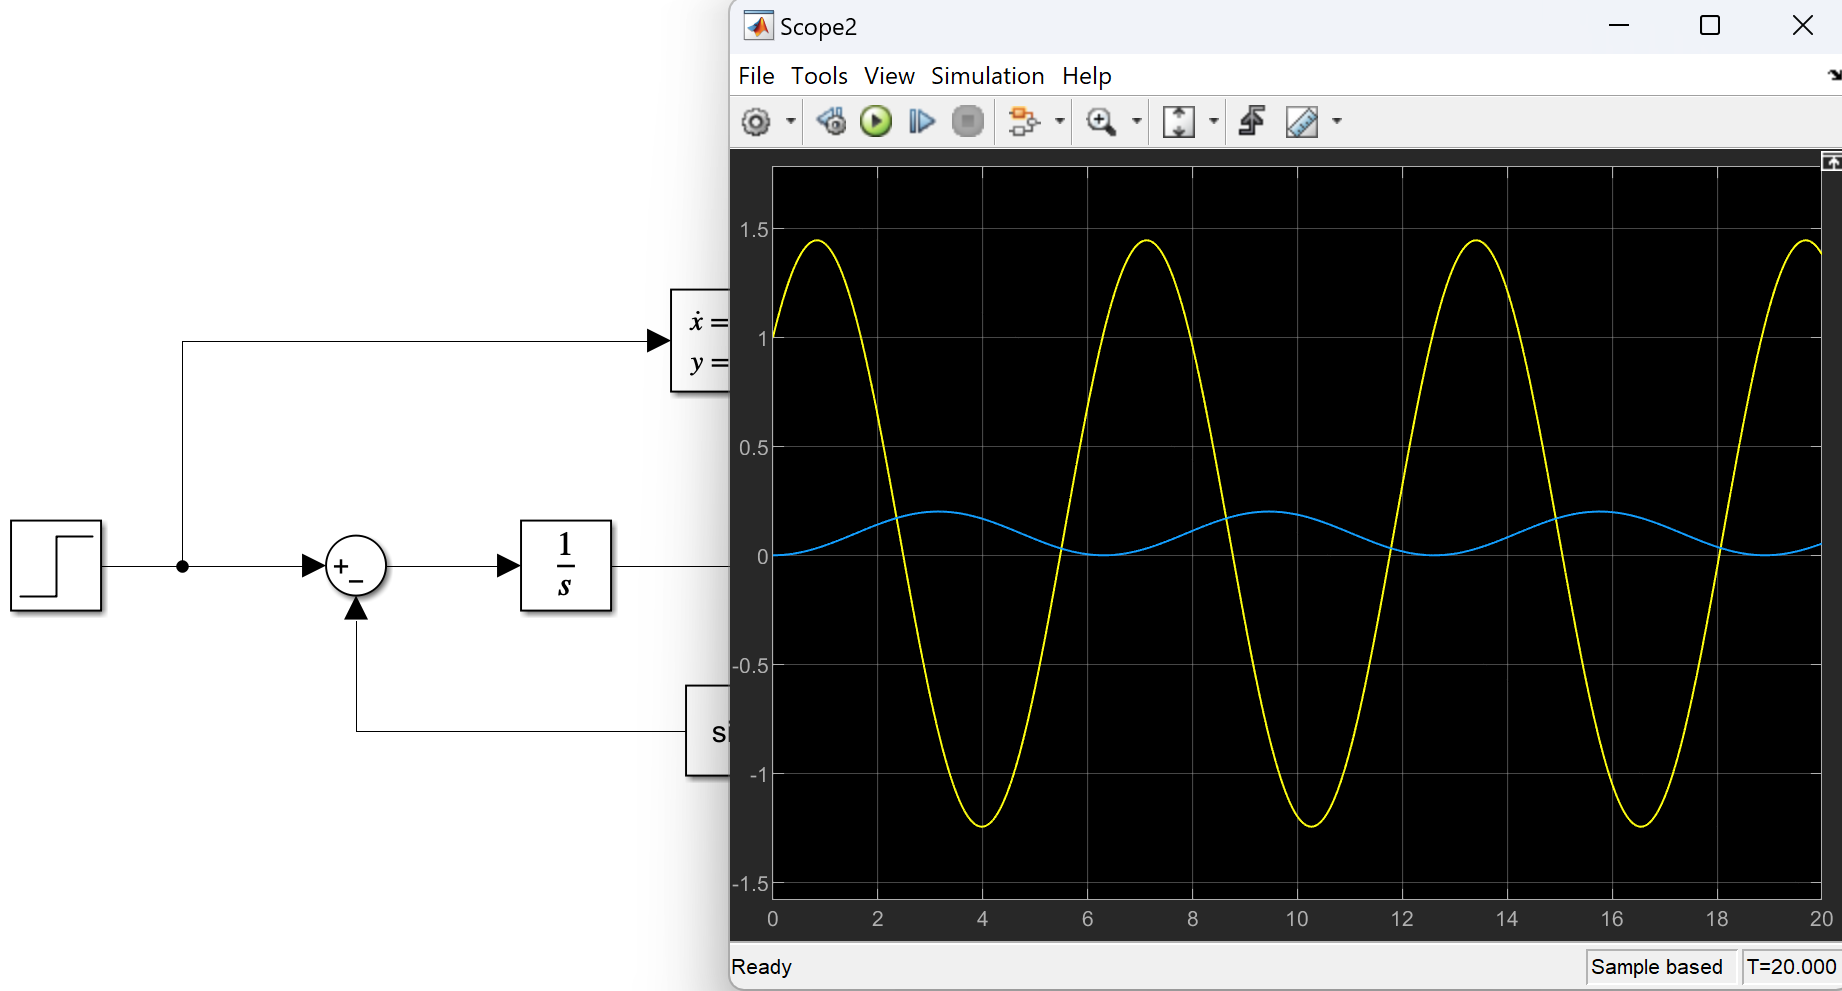

Initial Condition= 0.1:

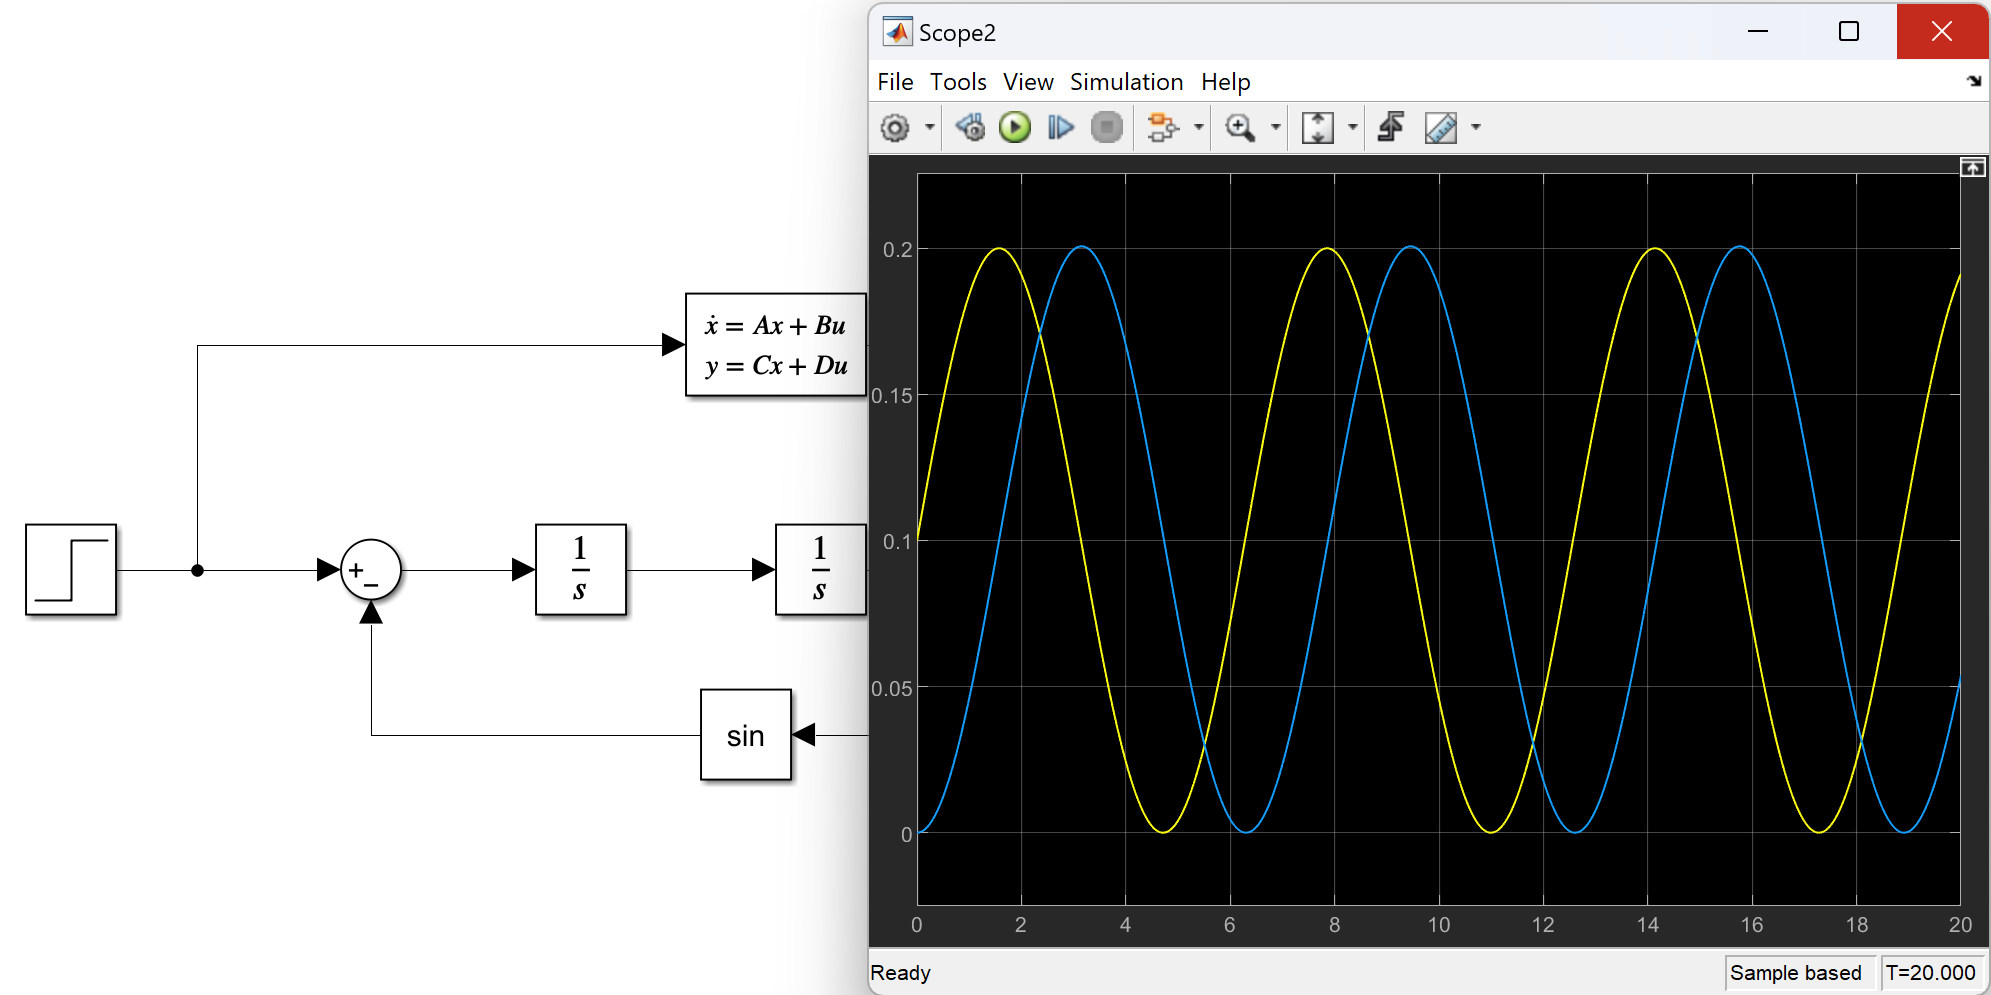

Initial Condition= 0.15

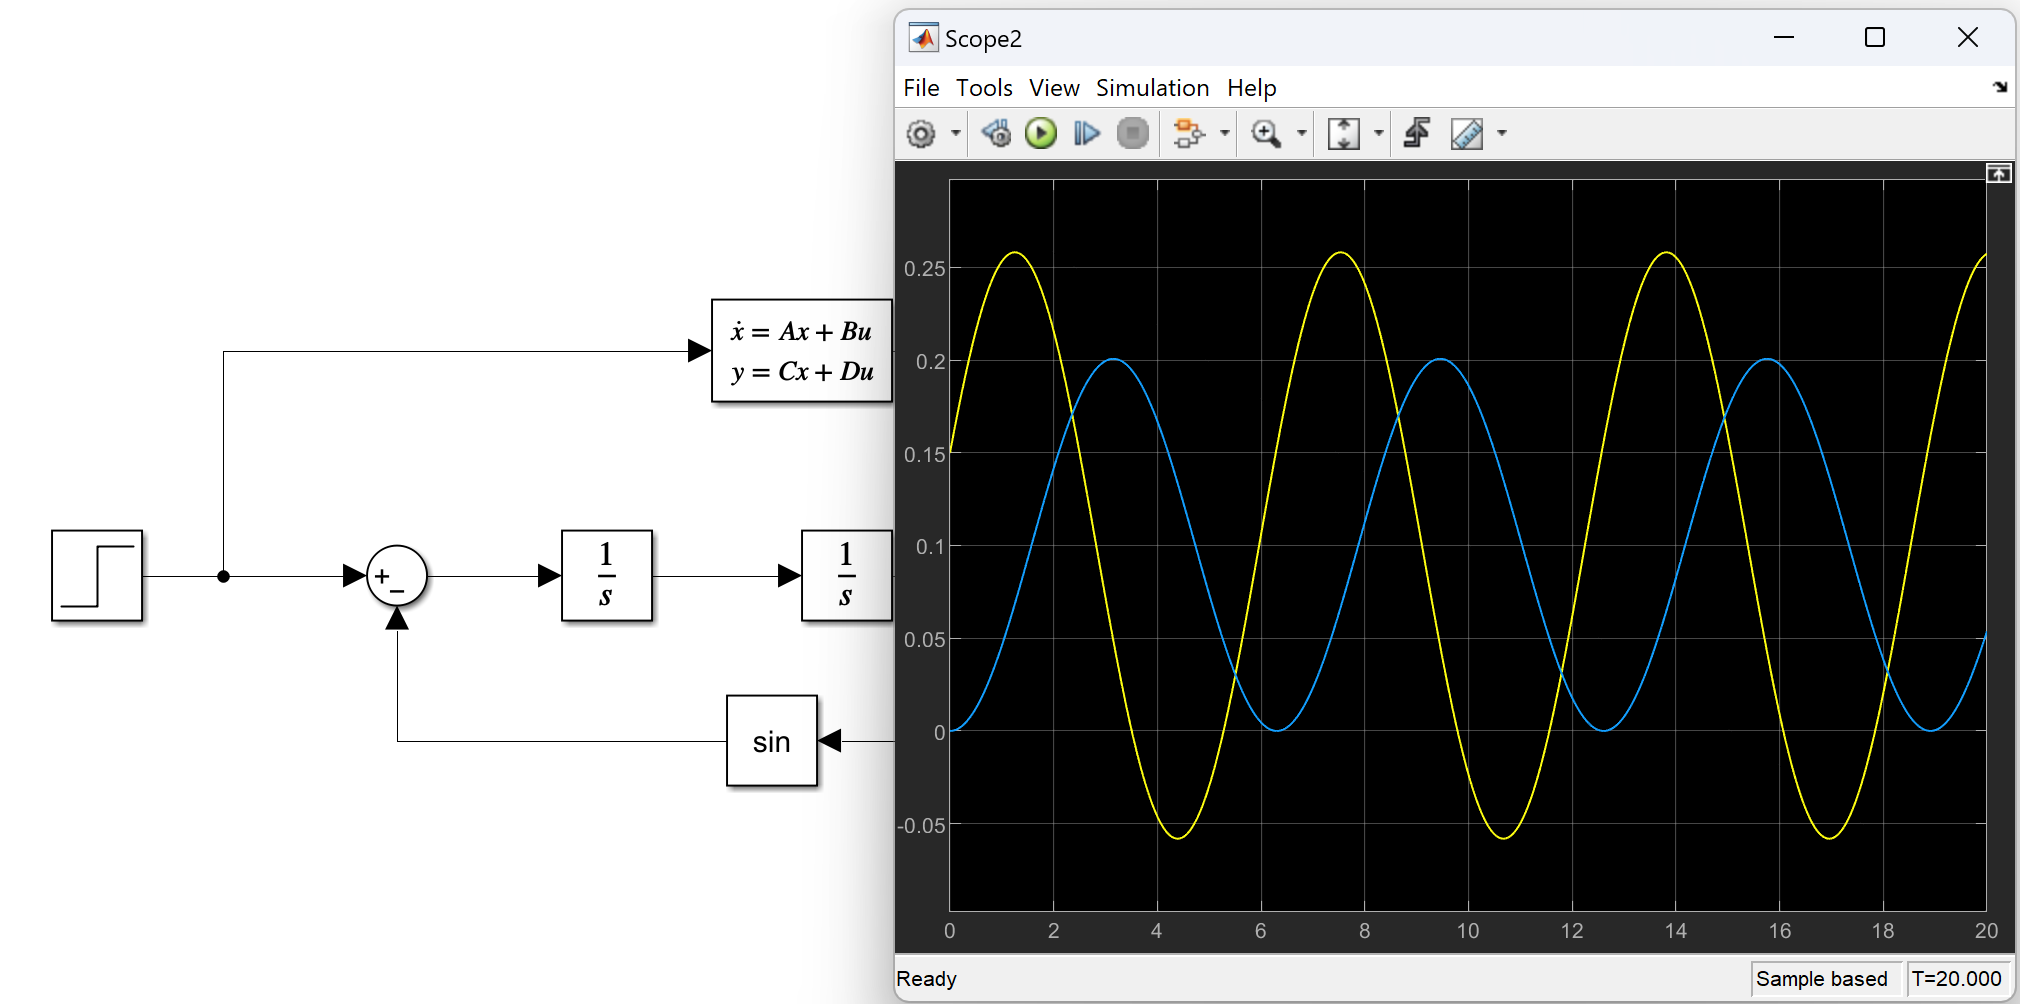

Initial Condition= -0.02

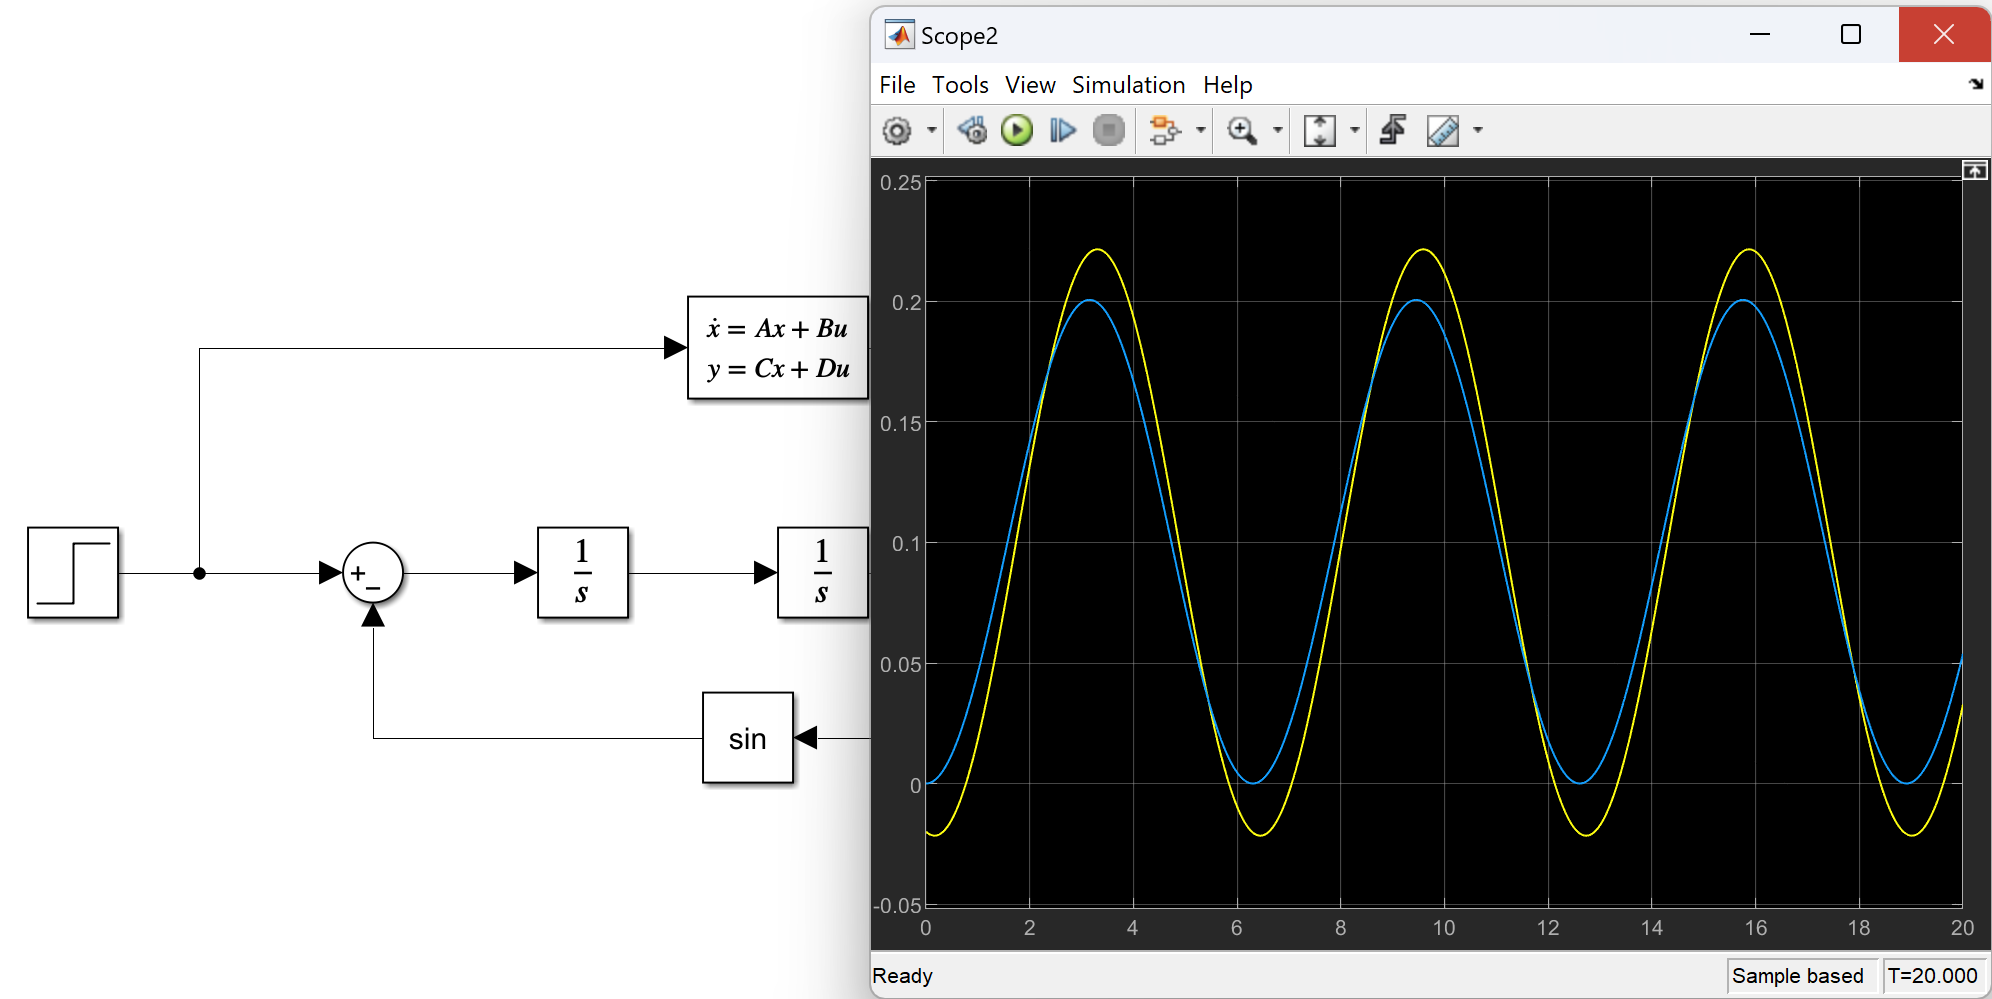

Range of initial Condtions: [ -0.01 : 0.1 ] around 0.